Classification Accuracy = 95.56%


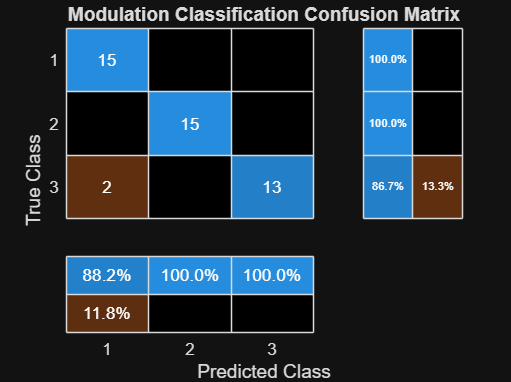

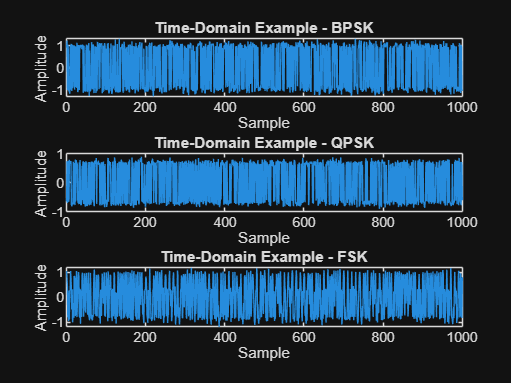

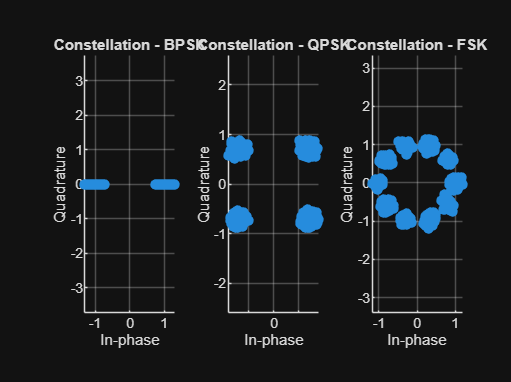

%% AI-Based Modulation Classification 
clc; clear; close all;


%% 1. Parameters
Nsym = 1000;        % Symbols per frame
numFrames = 50;     % Frames per modulation
Fs = 1000;          % Sampling frequency
SNR_dB = 20;        % AWGN SNR
modTypes = {'BPSK','QPSK','FSK'};

signals = [];
labels = [];

%% 2. Generate Signals and Labels
for idx = 1:length(modTypes)
    for f = 1:numFrames
        switch modTypes{idx}
            case 'BPSK'
                bits = randi([0 1], Nsym,1);
                modSig = 2*bits-1;  % BPSK symbols: -1, +1
            case 'QPSK'
                bits = randi([0 1], Nsym*2,1);
                symIdx = bi2de(reshape(bits, [],2));
                modSig = pskmod(symIdx,4,pi/4); % QPSK
            case 'FSK'
                bits = randi([0 1], Nsym,1);
                f1 = 100; f2 = 200;
                t = (0:Nsym-1)'/Fs;
                modSig = (bits==0).*exp(1j*2*pi*f1*t) + (bits==1).*exp(1j*2*pi*f2*t);
        end
        modSig = awgn(modSig, SNR_dB,'measured'); % Add noise
        signals = [signals; modSig];
        labels = [labels; repmat(modTypes(idx), length(modSig),1)];
    end
end

%% 3. Plot Input Signals for Each Modulation
figure('Name','Input Signals','NumberTitle','off');
for idx = 1:length(modTypes)
    % Extract first frame for each modulation type
    startIdx = (idx-1)*Nsym*numFrames + 1;
    modSig = signals(startIdx:startIdx+Nsym-1);
    
    subplot(length(modTypes),1,idx);
    plot(real(modSig));
    title(['Input Signal (Real Part) - ' modTypes{idx}]);
    xlabel('Sample Index');
    ylabel('Amplitude');
    grid on;
end

%% 4. Feature Extraction (Statistical)
featMat = [];
featLabels = [];
windowSize = Nsym;

for i = 1:windowSize:length(signals)
    if i+windowSize-1 > length(signals)
        break
    end
    seg = signals(i:i+windowSize-1);
    feat = [mean(real(seg)), var(real(seg)), skewness(real(seg)), kurtosis(real(seg)), ...
            mean(imag(seg)), var(imag(seg)), skewness(imag(seg)), kurtosis(imag(seg))];
    featMat = [featMat; feat];
    featLabels = [featLabels; labels(i)];
end

%% 5. Encode Labels to Numeric
uniqueLabels = unique(featLabels);
labelNum = zeros(size(featLabels));
for k = 1:length(uniqueLabels)
    labelNum(strcmp(featLabels, uniqueLabels{k})) = k;
end

%% 6. Train/Test Split
cv = cvpartition(labelNum,'HoldOut',0.3);
Xtrain = featMat(training(cv),:);
Ytrain = labelNum(training(cv));
Xtest  = featMat(test(cv),:);
Ytest  = labelNum(test(cv));

%% 7. Train SVM Classifier
SVMModel = fitcecoc(Xtrain,Ytrain);

%% 8. Prediction
YPred = predict(SVMModel,Xtest);

%% 9. Evaluate Performance
accuracy = sum(YPred==Ytest)/length(Ytest);
fprintf('\nClassification Accuracy = %.2f%%\n', accuracy*100);

%% 10. Confusion Matrix
figure('Name','Confusion Matrix','NumberTitle','off');
confusionchart(Ytest, YPred, 'RowSummary','row-normalized','ColumnSummary','column-normalized');
title('Modulation Classification Confusion Matrix');

%% 11. Plot Time-Domain Example for Each Modulation
figure('Name','Time-Domain Examples','NumberTitle','off');
for idx = 1:length(modTypes)
    modIdx = find(strcmp(featLabels, modTypes{idx}),1);
    modSig = signals((modIdx-1)*Nsym+1 : modIdx*Nsym);
    subplot(length(modTypes),1,idx);
    plot(real(modSig));
    title(['Time-Domain Example - ' modTypes{idx}]);
    xlabel('Sample'); ylabel('Amplitude'); grid on;
end

%% 12. Plot Constellation Diagrams
figure('Name','Constellation Diagrams','NumberTitle','off');
for idx = 1:length(modTypes)
    modIdx = find(strcmp(featLabels, modTypes{idx}),1);
    modSig = signals((modIdx-1)*Nsym+1 : modIdx*Nsym);
    subplot(1,length(modTypes),idx);
    scatter(real(modSig), imag(modSig), 'filled');
    title(['Constellation - ' modTypes{idx}]);
    xlabel('In-phase'); ylabel('Quadrature');
    grid on; axis equal;
end
